% clear work space
close all
clear variables
% include working variables
load variables.mat


% коэффициенты полинома линейной апроксимации
p_1 = polyfit(heat_logT, heat_logP, 1);

% коэфициенты полинома нелинейной апроксимации
p_3 = polyfit(heat_temp, heat_pres, 3);

% сгенерируем точки, равномерно расположенные на области определения данных
xx_ex = linspace(heat_temp(1), heat_temp(end), 100);
xx_lin = linspace(heat_logT(1), heat_logT(end), 100);

% получим значения полиномов в этих точках
yy_1 = polyval(p_1, xx_lin);
yy_3 = polyval(p_3, xx_ex);

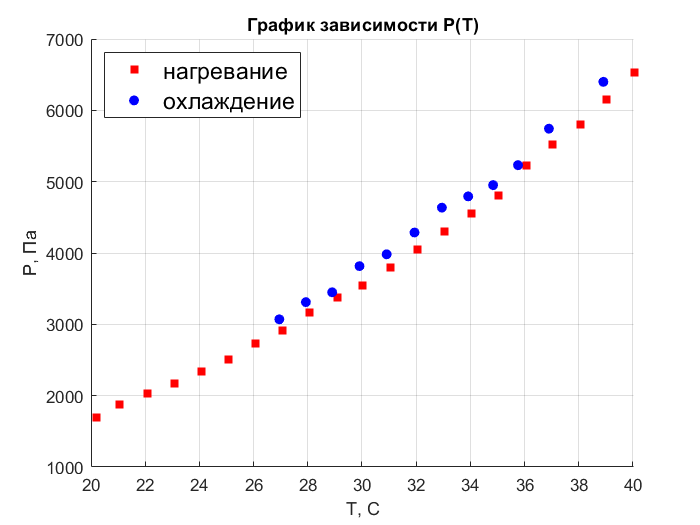

% экспоненчиальный график по точкам
fig1 = figure;

hold on
% эксперементальные точки, полученные при нагревании
scatter(heat_temp, heat_pres, 'filled', 'r', 's')
% эксперементальные точки, полученные при охлаждении
scatter(cool_temp, cool_pres, 'filled', 'b', 'c')

grid on
xlabel('T, C');
ylabel('P, Па');
title('График зависимости P(T)');
lnd = legend('нагревание', 'охлаждение', 'Location', 'northwest');
lnd.FontSize = 14;
hold off

set(fig1, 'Visible', 'on');

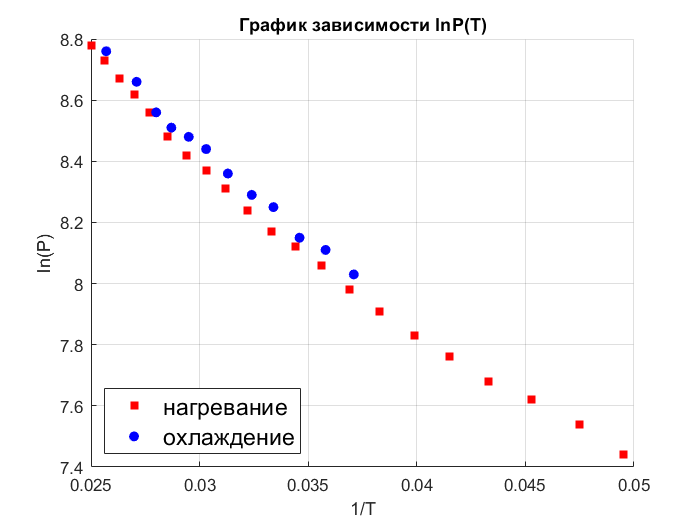

% линеализация графика
fig2 = figure;

% погрешности
%err = (heat_pres.^(-1)) * 9.42;

hold on
% эксперементальные точки, полученные при нагревании
scatter(heat_logT, heat_logP, 'filled', 'r', 's')
% эксперементальные точки, полученные при охлаждении
scatter(cool_logT, cool_logP, 'filled', 'b', 'c')
%errorbar(heat_logT, heat_logP, err, 'o')

grid on
xlabel('1/T');
ylabel('ln(P)');
title('График зависимости lnP(T)');
lnd = legend('нагревание', 'охлаждение', 'Location', 'southwest');
lnd.FontSize = 14;
hold off

set(fig2, 'Visible', 'on');

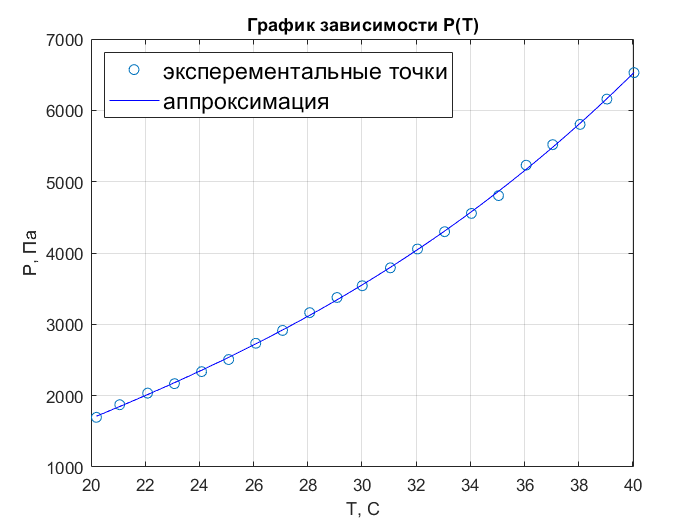

% аппроксимация экспоненциального графика
fig3 = figure;

plot(heat_temp, heat_pres, 'o', xx_ex, yy_3, 'b')

grid on
xlabel('T, C');
ylabel('P, Па');
title('График зависимости P(T)');
lnd = legend('эксперементальные точки', 'аппроксимация', 'Location', 'northwest');
lnd.FontSize = 14;

set(fig3, 'Visible', 'on');

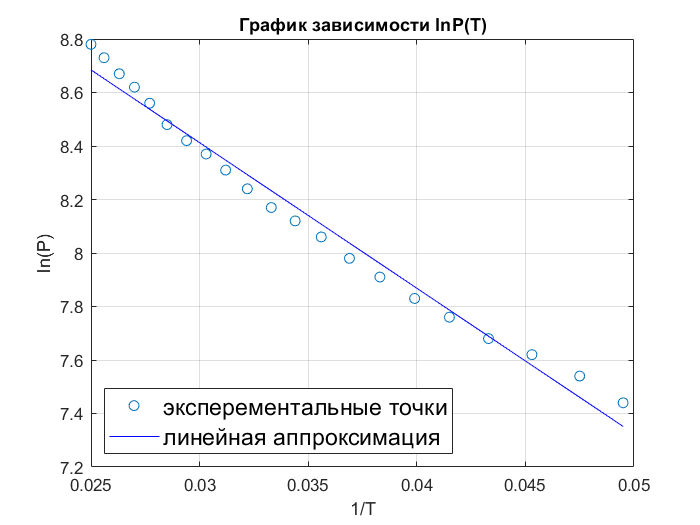

% линейное приближение МНК
fig4 = figure;

plot(heat_logT, heat_logP, 'o', xx_lin, yy_1, 'b')

grid on
xlabel('1/T');
ylabel('ln(P)');
title('График зависимости lnP(T)');
lnd = legend('эксперементальные точки', 'линейная аппроксимация', 'Location', 'southwest');
lnd.FontSize = 14;

set(fig4, 'Visible', 'on');

saveas(fig1, "P(T).png");

saveas(fig2, "lnP.png");

saveas(fig3, "approx_p(3).png");

saveas(fig4, "linear.png");